% rgb
map=([1 1 0; 1 0 0; 0 1 1; 0.2 0.2 0.2; 1 0 1; 0.8 0.8 0.8])

map =     1.0000    1.0000         0
    1.0000         0         0
         0    1.0000    1.0000
    0.2000    0.2000    0.2000
    1.0000         0    1.0000
    0.8000    0.8000    0.8000


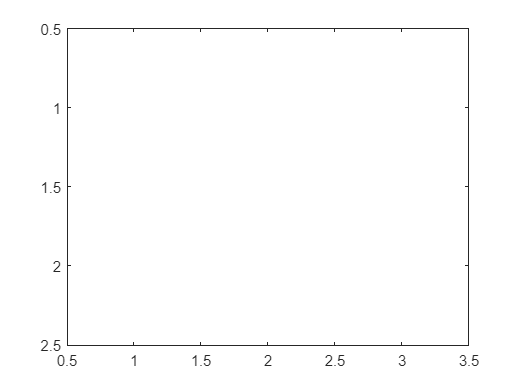

image([1 , 2 , 3; 4, 5, 6])
colormap(map)

N=[1 2 3; 4 5 6; 7 8 9; 10 11 12; 13 14 15]

N =      1     2     3
     4     5     6
     7     8     9
    10    11    12
    13    14    15


N(1:3:end, 1)

ans =      1
    10


N(1:3:end, :)

ans =      1     2     3
    10    11    12


v1=[1, 1, 1, 1]

v1 =      1     1     1     1


v2=[0.5, 0.25, 0, 0.25];
v3=[0.25, 0.5, 0, 0.5, 1]

v3 =     0.2500    0.5000         0    0.5000    1.0000


v1 .* v2

ans =     0.5000    0.2500         0    0.2500


s1=sum(v1 .* v2)

s1 = 1

%v1 .* v3
%s2=sum(v1 .* v3);

m6=[1 2 3; 4 5 6; 7 8 9];
m7=[-2 3 1; 0 2 -7; 1 3 6];

u1= m6>3

u1 = 3×3 logical array
   0   0   0
   1   1   1
   1   1   1


u2= (m6 > 3 & m7==-7)

u2 = 3×3 logical array
   0   0   0
   0   0   1
   0   0   0


u3= (m6 > 3 | m7==-7)

u3 = 3×3 logical array
   0   0   0
   1   1   1
   1   1   1


u4= ( (m6+m7) >= 4 & m6>5)

u4 = 3×3 logical array
   0   0   0
   0   0   0
   1   1   1


bild = imread('Butterfly.tif');
fargbild = double(bild) / 255;
mygray = (fargbild(:,:,1) + fargbild(:,:,2) + fargbild(:,:,3))/3;
imwrite(mygray, 'mygray.png');

mygrey = imread('mygray.png');
b61 = mygrey(1:2:end, 1:2:end);
imwrite(b61, 'b61.png');

b63_nearest = imresize(b61, 2, 'nearest');
b63_linear = imresize(b61, 2,'bilinear');
b63_cubic = imresize(b61, 2,'bicubic');

imwrite(b63_nearest, 'b63_nearest.png');
imwrite(b63_linear, 'b63_linear.png');
imwrite(b63_cubic, 'b63_cubic.png');

mycolorimage = imread('Butterfly.tif');
b64 = imresize(mycolorimage, 0.5, 'nearest');
b64 = imresize(b64, 2, 'nearest');
imshow(b64)
imwrite(b64, 'b64.png');

%6.5
mycolorR = mycolorimage(:, :, 1);
mycolorG = mycolorimage(:, :, 2);
mycolorB = mycolorimage(:, :, 3);

R2 = imresize(mycolorR, 0.5, 'nearest');
R2 = imresize(R2, 2, 'nearest');

B2 = imresize(mycolorB, 0.5, 'nearest');
B2 = imresize(B2, 2, 'nearest');

b65(:,:,1) = R2
b65(:,:,2) = mycolorG
b65(:,:,3) = B2

imwrite(b65, 'b65.png');

%6.7
R = mycolorimage(:, :, 1);
G = mycolorimage(:, :, 2);
B = mycolorimage(:, :, 3);

R3 = imresize(R, 0.5, 'nearest');
R3 = imresize(R3, 2, 'nearest');

G3 = imresize(G, 0.5, 'nearest');
G3 = imresize(G3, 2, 'nearest');

b67(:,:,1) = R3
b67(:,:,2) = G3
b67(:,:,3) = B

imwrite(b67, 'b67.png');

%6.8
bild1 = R + G + B
bild2 = R - G
bild3 = R + G - 2*B
bild2 = imresize(bild2, 0.5, 'nearest');
bild2 = imresize(bild2, 2, 'nearest');
bild3 = imresize(bild3, 0.5, 'nearest');
bild3 = imresize(bild3, 2, 'nearest');
b68(:,:,1) = bild1/3+bild2/2+bild3/6;
b68(:,:,2) = bild1/3-bild2/2+bild3/6;
b68(:,:,3) = bild1/3-bild3/3
imwrite(b68, 'b68.png')